ans = 252.9491

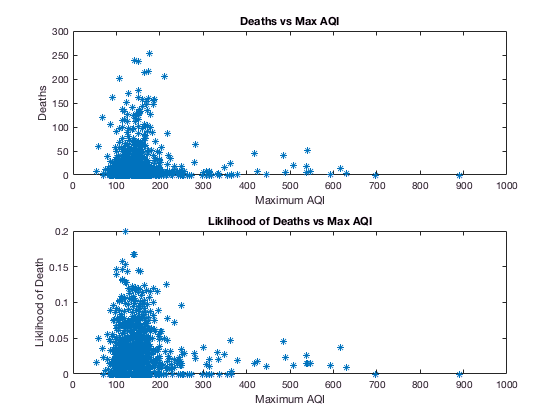

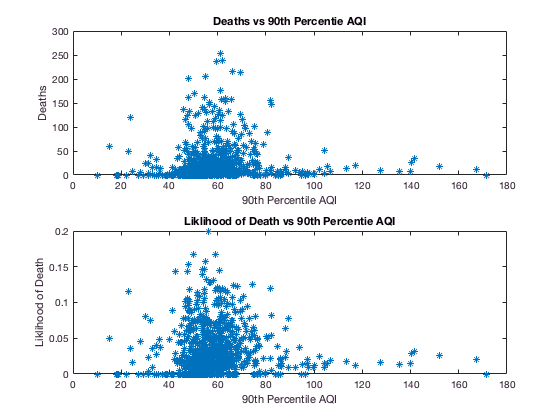

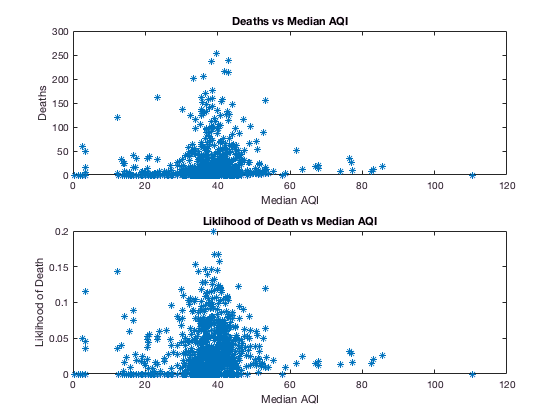

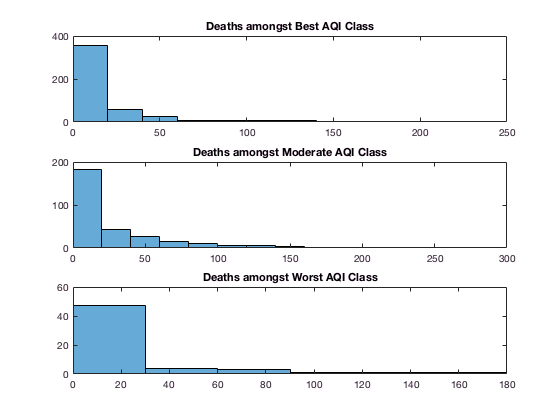

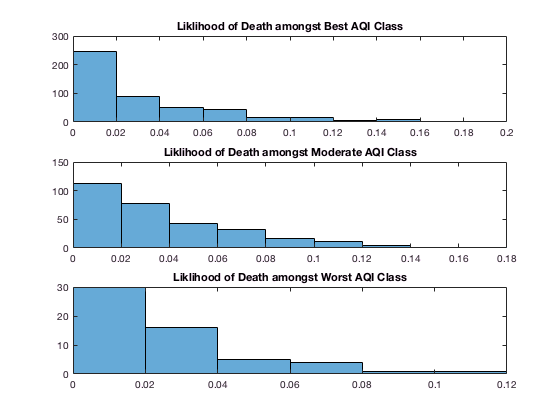

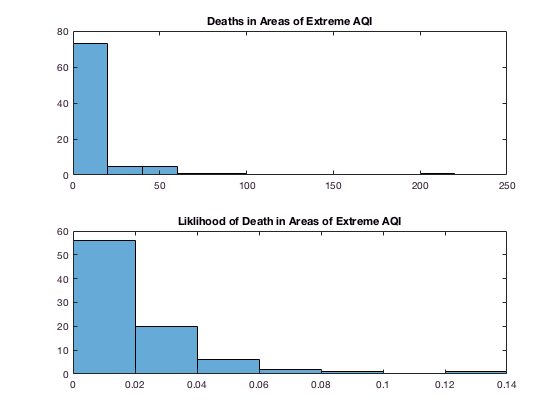

Features = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features.csv', 'ReadVariableNames',1);
MaxAQI = Features.MaxAQI;
per90 = Features.x90thPercentileAQI;
MedAQI = Features.MedianAQI;
AQI_Class_KM = Features.AQI_Class_KM;
AQI_Class_Extreme = Features.Extreme_AQI;

Deaths = Features.Norm_Deaths;

DeathsL = Features.Liklihood_Deaths;

max(Deaths)
DLedges = [0:0.0001:0.0025];
DLedges = [0:0.0001:0.0025];

% Deaths vs  Max AQI 
figure(1)
subplot(2,1,1)
plot(MaxAQI, Deaths, '*')
title('Deaths per 100 000 people vs Max AQI')
xlabel('Maximum AQI')
ylabel('Deaths')
xlim([0,1000])

subplot(2,1,2)
plot(MaxAQI, DeathsL, '*')
title('Liklihood of Deaths vs Max AQI')
xlabel('Maximum AQI')
ylabel('Liklihood of Death')
xlim([0,1000])

% Deaths vs 90% AQI
figure(2)
subplot(2,1,1)
plot(per90, Deaths, '*')
title('Deaths per 100 000 people vs 90th Percentie AQI')
xlabel('90th Percentile AQI')
ylabel('Deaths')

subplot(2,1,2)
plot(per90, DeathsL, '*')
title('Liklihood of Death vs 90th Percentie AQI')
xlabel('90th Percentile AQI')
ylabel('Liklihood of Death')

% Deaths vs Median AQI 
figure(3)
subplot(2,1,1)
plot(MedAQI, Deaths,'*')
title('Deaths per 100 000 people vs Median AQI')
xlabel('Median AQI')
ylabel('Deaths')

subplot(2,1,2)
plot(MedAQI, DeathsL,'*')
title('Liklihood of Death vs Median AQI')
xlabel('Median AQI')
ylabel('Liklihood of Death')

% Distribution of Deaths amongst AQI Classes 
Deaths_KM_1 = Deaths(AQI_Class_KM==1);
Deaths_KM_2 = Deaths(AQI_Class_KM==2);
Deaths_KM_3 = Deaths(AQI_Class_KM==3);

figure(4)
subplot(3,1,1)
histogram(Deaths_KM_1)
title('Deaths amongst Best AQI Class')
%ylim([0 275])

subplot(3,1,2)
histogram(Deaths_KM_2)
title('Deaths amongst Moderate AQI Class')
%ylim([0 275])

subplot(3,1,3)
histogram(Deaths_KM_3)
title('Deaths amongst Worst AQI Class')
%ylim([0 275])

% ACCOUNT FOR UNBALANCED CLASSES BEFORE MAKING ANY CLAIMSSSSSSSSS!!!
%title('Distribution of Deaths amongst AQI Classes')'


% Distribution of Liklihood of Death amongst AQI Classes 
DeathsL_KM_1 = DeathsL(AQI_Class_KM==1);
DeathsL_KM_2 = DeathsL(AQI_Class_KM==2);
DeathsL_KM_3 = DeathsL(AQI_Class_KM==3);

figure(5)
subplot(3,1,1) 
histogram(DeathsL_KM_1)
title('Liklihood of Death amongst Best AQI Class')
%ylim([0 275])

subplot(3,1,2)
histogram(DeathsL_KM_2)
title('Liklihood of Death amongst Moderate AQI Class')
%ylim([0 275])

subplot(3,1,3)
histogram(DeathsL_KM_3)
title('Liklihood of Death amongst Worst AQI Class')
%ylim([0 275])

% ACCOUNT FOR UNBALANCED CLASSES BEFORE MAKING ANY CLAIMSSSSSSSSS!!!
%title('Distribution of Deaths amongst AQI Classes')

Extreme_Deaths = Deaths(AQI_Class_Extreme==1);
Extreme_DeathsL = DeathsL(AQI_Class_Extreme==1);

figure(6)
subplot(2,1,1)
histogram(Extreme_Deaths)
title('Deaths per 100 000 people in Areas of Extreme AQI')

subplot(2,1,2)
histogram(Extreme_DeathsL)
title('Liklihood of Death in Areas of Extreme AQI')

Features = 832×13 table
         State                  County                          CS                   MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    Extreme_AQI    Norm_Cases    Norm_Deaths    Liklihood_Deaths    Case_Det_Class    Case_Spectral_Class
    ________________    ______________________    _______________________________    ______    __________________    _________    ____________    ___________    __________    ___________    ________________    ______________    ___________________

    'Alabama'           'Baldwin'    